clear all
%Plot the raw trajectory
sn = 'Ind003';
sess = 'A1';
block = 'B1';
hand = 'Right';

base_dir = fullfile('/Users/patrick/Documents/Projects/HandSignature/Data/ConcatenatedData/20230425/Raw_Data/');
subj_dir = sn;
Yml_dir = '/Users/patrick/Documents/Projects/HandSignature/Data/ConcatenatedData/20232501/20232501_SubjectYML/';

sess_dir = fullfile(base_dir,subj_dir,[append('/',sess,'/')]);

path = fullfile('/Users/patrick/Documents/Projects/HandSignature/Data/ConcatenatedData/20232501/Plots/DSData_Trajectories/',sn,'/');

log_file = [sn '_' sess '_' hand,'_log.yml'];

L = yaml.ReadYaml(fullfile(Yml_dir,log_file));

%Read in and save variables from the YML File
r(1)   = 5-str2num(L.Thumb.DEVICEMountLength);
r(2)   = 5-str2num(L.Index.DEVICEMountLength);
r(3)   = 5-str2num(L.Middle.DEVICEMountLength);
r(4)   = 5-str2num(L.Ring.DEVICEMountLength);
r(5)   = 5-str2num(L.Pinky.DEVICEMountLength);
ang(1) = str2num(L.Thumb.DEVICEMountAngle);
ang(2) = str2num(L.Index.DEVICEMountAngle);
ang(3) = str2num(L.Middle.DEVICEMountAngle);
ang(4) = str2num(L.Ring.DEVICEMountAngle);
ang(5) = str2num(L.Pinky.DEVICEMountAngle);
fcenter = zeros(5,3);
for f=1:5
    fcenter(f,1) = r(f)*cosd(180+ang(f)); % x
    fcenter(f,2) = r(f)*sind(180+ang(f)); % y
end

fcenter(1,1) = fcenter(1,1)-5;
fcenter(1,2) = fcenter(1,2)+3;
fcenter(2,1) = fcenter(2,1)-2.5;
fcenter(2,2) = fcenter(2,2)+4.5;
fcenter(3,1) = fcenter(3,1)-0; % treat middle finger as the center
fcenter(3,2) = fcenter(3,2)+5;
fcenter(4,1) = fcenter(4,1)+2.5;
fcenter(4,2) = fcenter(4,2)+4.5;
fcenter(5,1) = fcenter(5,1)+5;
fcenter(5,2) = fcenter(5,2)+3;
fcenter = fcenter./10.*9.8;% convert to Newtons

%Define the fingers and the Trials
Fing = (1:16);
Fing = num2str(Fing);

Fings2 = repelem(1:24,1,4);
Fings2 = num2str(Fings2);

Fings = horzcat(Fing,Fings2);
 


Fingers = vertcat(repelem('1',16,1),repelem('2',24,1),repelem('3',24,1),repelem('4',24,1),repelem('5',24,1));

% Direction3 = vertcat("X","X","Z","Z");

Fings = 28×1 string array
    "Thumb"
    "Thumb"
    "Thumb"
    "Thumb"
    "Index"
    "Index"
    "Index"
    "Index"
    "Index"
    "Index"
    "Middle"
    "Middle"
    "Middle"
    "Middle"
    "Middle"
    "Middle"
    "Ring"
    "Ring"
    "Ring"
    "Ring"
    "Ring"
    "Ring"
    "Pinky"
    "Pinky"
    "Pinky"
    "Pinky"
    "Pinky"
    "Pinky"


% Direction2 = vertcat("X","X","Y","Y","Z","Z");
% Direction2 = repmat(Direction2,4,1);
% Direction3 = vertcat(Direction3,Direction2);

Trials = vertcat("Negative","Positive","Negative","Positive");
Trials2 = vertcat("Negative","Positive","Negative","Positive","Negative","Positive");
Trials2 = repmat(Trials2,4,1);
Trials = vertcat(Trials,Trials2);

Tasks = vertcat('x_','x_','z_','z_');
Tasks2 = vertcat('x_','x_','y_','y_','z_','z_');
Tasks2 = repmat(Tasks2,4,1);
Tasks = vertcat(Tasks,Tasks2);
Direction = vertcat('neg','pos');
Direction = repmat(Direction,14,1);

for pl = 1:3
    fcenter2{pl} = repmat((transpose([fcenter(:,pl)]')), [1,15]);
end

color = [0,0,0;0,0,0;0,0,0;0,0,0;0,0,0];
lim = [-10 10];
linelim = [-6 6];



for i = 1:length(Fings)
%     Trial{i,1} = strcat(Tasks(i,:),Direction(i,:));
%     MOV{i,1} = csvread(fullfile(sess_dir,[sn, '_', sess, '_', hand,'_', '_F' Fingers(i), '_', Trial{i}, '.csv']));
%     figPath{i,1} = fullfile(path,[sn, '_', sess, '_', hand, '_F' Fingers(i), '_', Trial{i}]);
    MOV{i,1} = csvread(fullfile(sess_dir,[sn, '_', sess, '_', hand,'_',block, '_F' Fingers(i), '_', Fings(i,:), '.csv']));
    figPath{i,1} = fullfile(path,[sn, '_', sess, '_', hand,block, '_F' Fingers(i), '_', Fings(i,:)]);
    force{i,1} = MOV{i}(:,1:15).*9.8
    baseline{i,1} = median(force{i}(1:100,:));
    normf{i,1} = bsxfun(@minus, force{i}, baseline{i});
    v{i,1} = VideoWriter(figPath{i});
    v{i}.FrameRate = 60;
    traj{i} = [normf{i}(:,1:3:end)+fcenter(:,1)',normf{i}(:,2:3:end)+fcenter(:,2)',normf{i}(:,3:3:end)+fcenter(:,3)'];
    fx{i} = fcenter2{1}(:,i);
    fy{i} = fcenter2{2}(:,i);
    fz{i} = fcenter2{3}(:,i);
    f = figure;
    scatter3(fx{i},fy{i},fz{i},[60 60 60 60 60],color,'filled');
    title([sn, Fings(i),Direction3(i),Trials(i),' Raw Trajectory'])
    hold on
    plot3(traj{i}(:,(1:5)),traj{i}(:,(6:10)),traj{i}(:,(11:15)));
    xlabel('X'); ylabel('Y'); zlabel('Z');
    line(linelim, [0,0], [0,0],'Color', 'k');
    line([0,0], linelim, [0 0],'Color', 'k');
    line([0,0], [0,0], linelim,'Color', 'k');
    set(gca,'XLim',lim,'YLim',lim,'ZLim',lim);
    %set(gca,'visible','off');
    frame = getframe(gcf);
    grid on
    hold off
%     saveas(f,[figPath{i}],'jpeg');
%     saveas(f,[figPath{i}],'fig');
end

Error using csvread
File not found.

close all

%%2D Trajectory Plots
clear all 
subject = 'IndP005'

subject = 'IndP001'

sess = 'A1'

sess = 'A1'

hand = 'Left'

hand = 'Left'

% Trials = [subject,'_A1_Right_F1_z_pos']
Fingers = vertcat(repelem('1',4,1),repelem('2',6,1),repelem('3',6,1),repelem('4',6,1),repelem('5',6,1));

Tasks = vertcat('x_','x_','z_','z_');
Tasks2 = vertcat('x_','x_','y_','y_','z_','z_');
Tasks2 = repmat(Tasks2,4,1);
Tasks = vertcat(Tasks,Tasks2);
Direction = vertcat('neg','pos');
Direction = repmat(Direction,14,1);

cNum = [repelem(1,2),repelem(3,2)]

cNum =      1     1     3     3


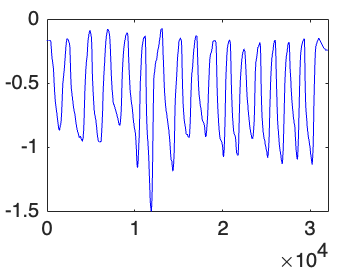

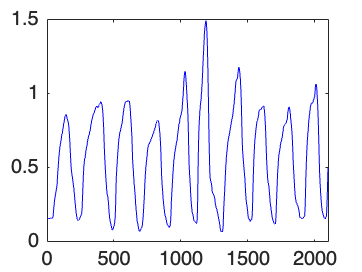

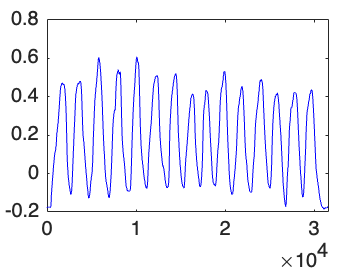

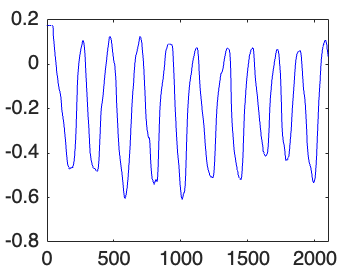

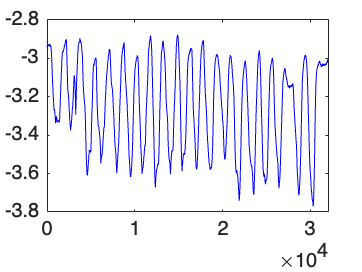

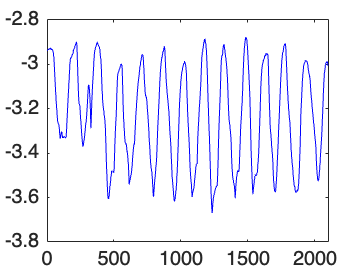

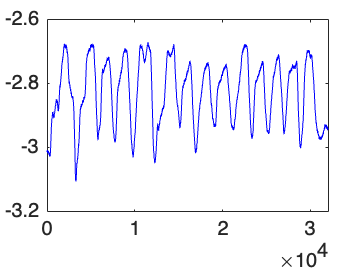

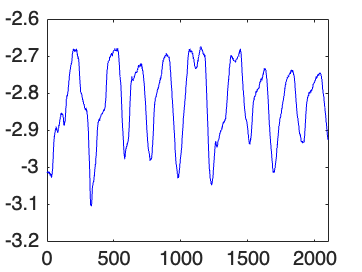

cNum2 = [repelem(4:15,2)];
cNum = horzcat(cNum,cNum2);

for i = 1:28
Trial{i,1} = strcat(Tasks(i,:),Direction(i,:));
Trials{i,1} = [subject, '_', sess, '_', hand, '_F' Fingers(i), '_', Trial{i}];
figpath1{i,1} = fullfile('/Users/patrick/Documents/Projects/HandSignature/Data/ConcatenatedData/20232501/Plots/2D_RAWTrajectories',subject,'/',Trials{i});
figpath2{i,1} = fullfile('/Users/patrick/Documents/Projects/HandSignature/Data/ConcatenatedData/20232501/Plots/2D_DSDataTrajectories',subject,'/',Trials{i});
Trajectory{i,1} = csvread(['/Users/patrick/Documents/Projects/HandSignature/Data/ConcatenatedData/20232501/20232501_RawData/',subject,'/',Trials{i}, '.csv']);
Trajectory1{i,1} = csvread(['/Users/patrick/Documents/Projects/HandSignature/Data/ConcatenatedData/20232501/20232501_DSData/',subject,'/',Trials{i}, '.csv']);
f = figure;
plot(Trajectory{i,1}(:,cNum(i)),'blue');
saveas(f,figpath1{i,1},'jpeg');
saveas(f,figpath1{i,1},'fig');
f2 = figure;
plot(Trajectory1{i,1}(:,cNum(i)),'blue');
saveas(f2,figpath2{i,1},'jpeg');
saveas(f2,figpath2{i,1},'fig');
end

close all
%%Thumb = 1:3, Index = 4:6, Middle = 7:9, Ring = 10:12, Pinky = 13:15

% %Oscillatory Averaging of Raw Data
% for k = 1:length(unique(Fingers)) %Fingers (1 = Thumb, 5 = Pinky)
%     kk{k,1} = (k:length(unique(Fingers)):length(unique(Fingers))*5); %Matches XYZ Trajectories for each finger
%     for j = 1:length(Tasks) %Generalize this later
%         Tble{j,k} = traj{j}(:,kk{k}(1:3));
%         ndata{j,k} = Tble{j,k}(1:fix(length(Tble{j,k})),:); %Length of data is 1675, and is best divisible when reduced by 75 to 1600
%         samples{j,k} = floor((1/4)*length(ndata{j,k})); %Every 1/16th sample seems to be the best Sample Averaging range
%         i1{j,k} = 1:samples{j,k}:length(ndata{j,k});
%         ii1{j,k} = [1:samples{j,k}:length(ndata{j,k}),length(ndata{j,k})];
%         ii1{j,k} = ii1{j,k}(2:width(ii1{j,k}));
%         for u = 1:width(ii1{1,1});
%             for t = 1:width(ndata{1,1})
%                 stuff{j,k}{u,t} = ndata{j,k}((i1{j,k}(u):ii1{j,k}(u)),t);
%             end
%         end 
%     end
% end
% 
% %Plotting the different data oscillations over each other
% for k = 1:length(unique(Fingers))
%     for j = 1:length(Tasks) %Generalize this later
%         for jk = 1:(width(ii1{1,1})-1)
%         plot(stuff{1,1}{jk,1});
%         hold on
%         end
%     end
% end
% hold off
% for k = 1:length(unique(Fingers))
%     for j = 1:length(Tasks) %Generalize this later
%         for jk = 1:(width(ii1{1,1})-1)
%         plot(stuff{1,1}{jk,2});
%         hold on
%         end
%     end
% end
% hold off
% for k = 1:length(unique(Fingers))
%     for j = 1:length(Tasks) %Generalize this later
%         for jk = 1:(width(ii1{1,1})-1)
%         plot(stuff{1,1}{jk,3});
%         hold on
%         end
%     end
% end
% hold off
% %Regular Average
% for j = 1:length(Tasks)
%     for k = 1:length(unique(Fingers))
%     xDim{j,k} = horzcat(stuff{j,k}{1:length(stuff{j,k})-1,1});
%     yDim{j,k} = horzcat(stuff{j,k}{1:length(stuff{j,k})-1,2});
%     zDim{j,k} = horzcat(stuff{j,k}{1:length(stuff{j,k})-1,3});
%     avg_xDim{j,k} = mean(xDim{j,k},2);
%     avg_yDim{j,k} = mean(yDim{j,k},2);
%     avg_zDim{j,k} = mean(zDim{j,k},2);
%     end
% end
% 
% %1 = Thumb X
% %6 = Thumb Y
% %11 = Thumb Z
% %%Plotting for One Finger Across 28 trials
% 
% for k = 1:length(unique(Fingers)) %Fingers (1 = Thumb, 5 = Pinky)
%     kk{k,1} = (k:length(unique(Fingers)):length(unique(Fingers))*3);
%     l(k) = figure(k)
%     plot3(traj{1}(:,kk{k}(1)),traj{1}(:,kk{k}(2)),traj{1}(:,kk{k}(3)),'r')
%     hold on
%     plot3(avg_xDim{1,k},avg_yDim{1,k},avg_zDim{1,k},'b',LineWidth=3)
%     grid on
%     hold off
% end

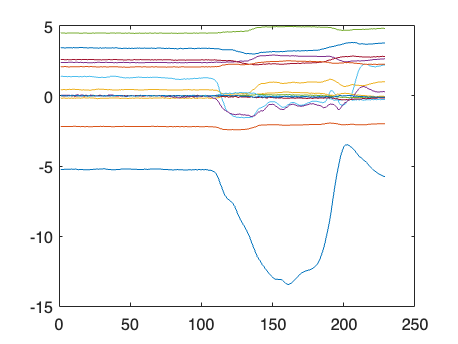

%Second Averaging Technique


%%Plot XYZ vectors in 2D
plot(traj{1,1})

%%Find Specific peaks across each vector
%%Break XYZ Vectors according to Peak to Peak intervals
%%Use Interpolation and Moving Average to Average data
%%Plot Averaged data w/ Non-Averaged Data